clear all
close all
%data.mat
%Objective of Project: Implement different classifiers to achieve face
%recognition
data = load('data.mat');
face = data.face;
face_neutral = face(:,:,1:3:end);%neutral faces (first face)
face_exp = face(:,:,2:3:end);%smiling faces (second face)
face_illum = face(:,:,3:3:end);%illuminating faces (third face)

%imshow(face(:,:,1));
%200 subjects (people) 
% 3 faces per subject (200*3 = 600 faces)
% size: 24 x 21
% 
% The file 'data.mat' has a variable ”face” of size (24x21x600). The images corresponding to the
% person labeled n, n = {1, . . . , 200}, can be indexed in Matlab as face(:,:,3*n-2), face(:,:,3*n-1)
% and face(:,:,3*n). The first image is a neutral face, the second image is a face with facial
% expression, and the third image has illumination variations.

%%face_Neu = face_neutral(:,:,1:100);
%size(face_Neu)
%face_smile = face_exp(:,:,1:100);
%size(face_Neu)

%Attempt 1: Fisher linear Discriminant -- not needed for project/ doesn't
%work --- plot code has now been removed in this doc
%Below variables are needed
[d1, d2, n] = size(face_neutral); 
X1 = zeros(n,d1*d2);%data for neutral faces
X2 = zeros(n,d1*d2);%data for smiling faces
for j = 1:n
    aux = face_neutral(:,:,j);
    X1(j,: ) = aux(:)';
    aux = face_exp(:,:,j);
    X2(j,:) = aux(:)';
end

n1 = n;
n2 = n;
m1 = mean(X1,1);%column mean for X1
m2 = mean(X2,1);%column mean for X2
Xc1 = X1-ones(n1,1)*m1; %center X1
S1 = Xc1'*Xc1; %scatter matrix for X1
Xc2 = X2-ones(n2,1)*m2; %center X2
S2 = Xc2'*Xc2;%scatter matrix for X2
Sw = S1+S2;%compute the within-class scatter
%note: d = m*m > n, hence we solve the generalized eigenvalue problem.

Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw);
lam = diag(lam0);
[lam, isort] = sort(lam,'descend');

W = W(:,isort);
W = W(:,1);
X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;
y = X*W;

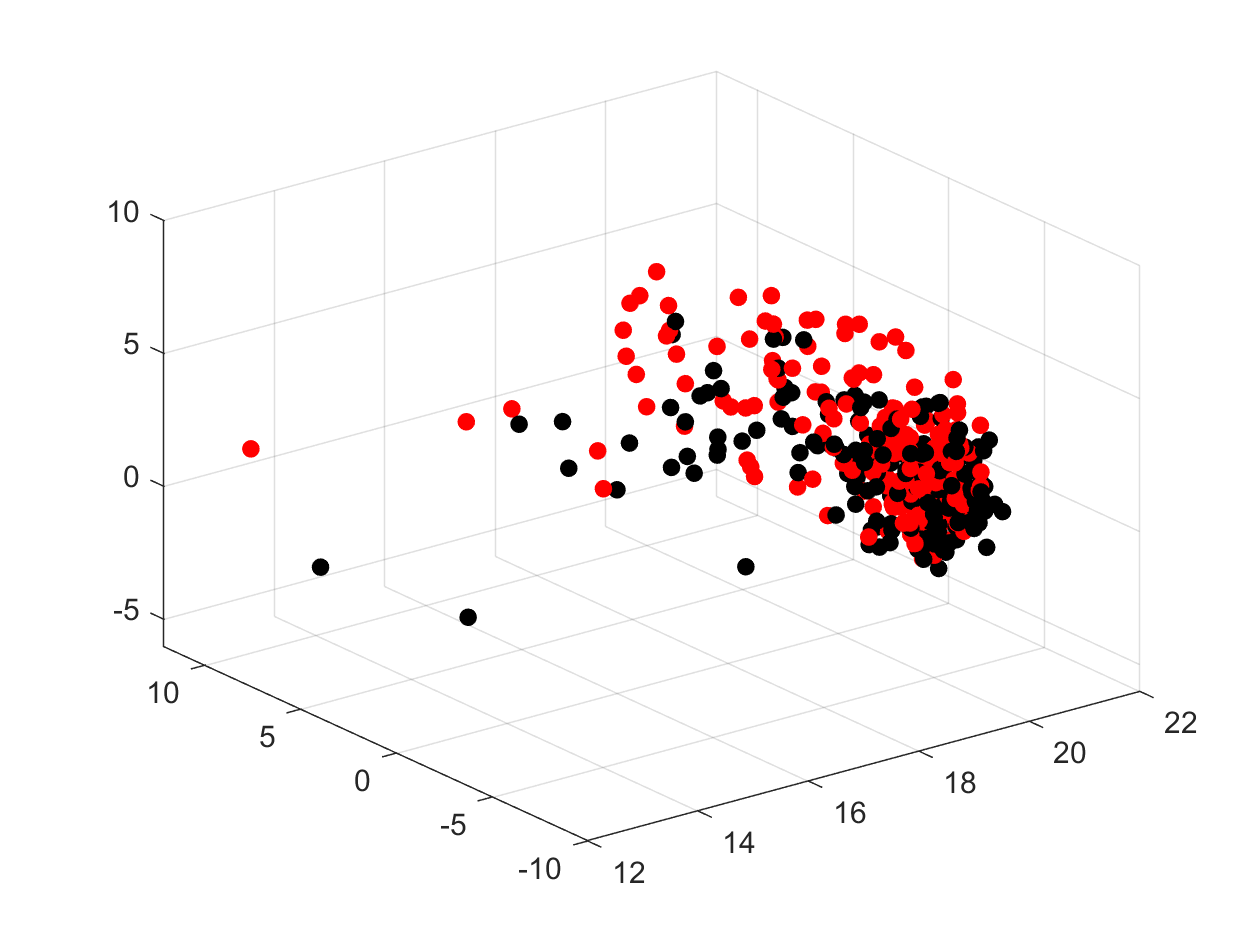

%Map the data to a higher dimensional space using -- PCA --
[U,Sig,V] = svd(X','econ');
nPCA =100;
%project to nPCA-dimensional space
Y = X*U(:,1:nPCA);
figure;
hold on;
grid;
plot3(Y(D1,1),Y(D1,2),Y(D1,3),'.','Markersize',20,'color','k');
view(3);
plot3(Y(D2,1),Y(D2,2),Y(D2,3),'.','Markersize',20,'color','r');
view(3);%makes plot 3D

%Now apply k - Nearest Neighbor

Ntrain = 100; % what is the percentage split
Ntest = n-Ntrain;
train1 = 1:Ntrain;
train2 = (n+1):(n+Ntrain);
test1 = (Ntrain+1):n;
test2 = (n+Ntrain+1):(2*n);
train_idx = [train1, train2];
test_idx = [test1, test2];
Ytrain = Y(train_idx,:); %train data in PCA space
%in Ytrain, the first Ntest rows -> neutral, the last Ntest rows -> smily
Ytest = Y(test_idx,:); %test data in PCA space

kNN = 5;
labels = zeros(length(test_idx),1);
for j = 1:length(test_idx)
    ytest = Ytest(j,:);
    dist_sq = sum((Ytrain - ones(size(Ytrain,1),1)*ytest).^2,2);
    [dsort, isort] = sort(dist_sq,'ascend');
    k_near_neib = isort(1:kNN);
    knn_neutral = find(k_near_neib <= Ntrain);
    knn_smile = find(k_near_neib > Ntrain);
    if length(knn_neutral) > length(knn_smile)
        labels(j) = 1;
    else
        labels(j) = -1; 
    end
end

iplus = find(labels > 0);
iminus = find(labels < 0);
fprintf('#iplus = %d, #imunus = %d\n',length(iplus),length(iminus));

#iplus = 128, #imunus = 72
